# FF_SAVEBORR_GRID Example for Generating Asset Grid

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

This is the example vignette for function: [**ff_nonimg_posnegbd**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/generate/ff_nonimg_posnegbd.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function checks for valid domain for function that generates real-valued outcomes, and identifies values along the domain that generates positive and negative Values. 

## Test FF_NONIMG_POSNEGBD Defaults

Call the function with defaults.

FF_NONIMG_POSNEGBD;it_exit_condition=6;bl_has_increase=0;bl_has_decrease=1;bl_has_constant=0;bl_has_pos=0;bl_has_neg=1;bl_has_zero=0


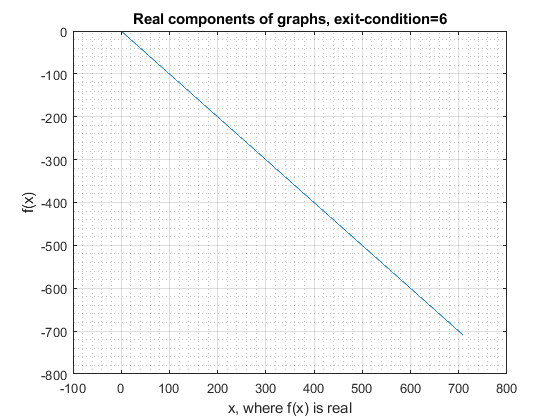

ff_nonimg_posnegbd();

## Test FF_NONIMG_POSNEGBD with Log(x)

Testing the function with log(x) 

FF_NONIMG_POSNEGBD;it_exit_condition=1;bl_has_increase=1;bl_has_decrease=0;bl_has_constant=0;bl_has_pos=1;bl_has_neg=1;bl_has_zero=0


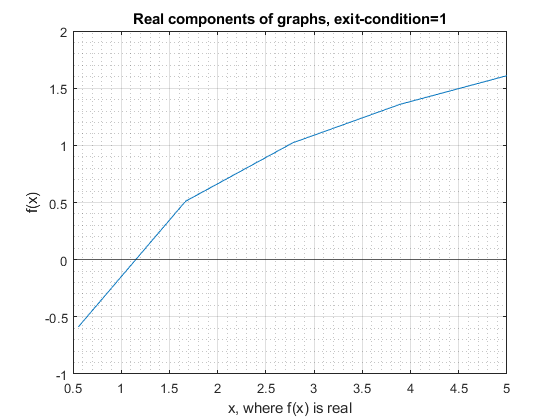

% Same min and max and grid points
[fl_x_min, fl_x_max, it_eval_points, it_eval_max_round, bl_loop] = deal(-5, 5, 10, 3, true);
[bl_verbose, bl_timer] = deal(true, true);
fc_eval = @(x) log(x);
% Solve
[ar_x_points_noimg, ar_obj_eval_noimg, aar_obj_eval_noimg] = ...
    ff_nonimg_posnegbd(fl_x_min, fl_x_max, fc_eval, it_eval_points, it_eval_max_round, bl_loop, ...
    bl_verbose, bl_timer);